# Estimate States Online Using Particle Filter

Load the van der Pol ODE data, and specify the sample time. 

`vdpODEdata.mat` contains a simulation of the van der Pol ODE with nonlinearity parameter mu=1, using ode45, with initial conditions `[2;0]`. The true state was extracted with sample time `dt = 0.05`.

load ('vdpODEdata.mat','xTrue','dt')
tSpan = 0:dt:5;

Get the measurements. For this example, a sensor measures the first state with a Gaussian noise with standard deviation `0.04`.

sqrtR = 0.04;
yMeas = xTrue(:,1) + sqrtR*randn(numel(tSpan),1);

Create a particle filter, and set the state transition and measurement likelihood functions.

myPF = particleFilter(@vdpParticleFilterStateFcn,@vdpMeasurementLikelihoodFcn);

Initialize the particle filter at state `[2; 0]` with unit covariance, and use `1000` particles.

initialize(myPF,1000,[2;0],eye(2));

Pick the `mean` state estimation and `systematic` resampling methods.

myPF.StateEstimationMethod = 'mean';
myPF.ResamplingMethod = 'systematic';

Estimate the states using the `correct` and `predict` commands, and store the estimated states.

xEst = zeros(size(xTrue));
for k=1:size(xTrue,1)
    xEst(k,:) = correct(myPF,yMeas(k));
    predict(myPF);
end

Plot the results, and compare the estimated and true states. 

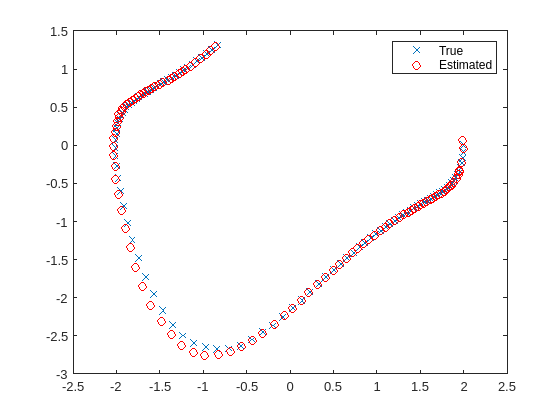

figure(1)
plot(xTrue(:,1),xTrue(:,2),'x',xEst(:,1),xEst(:,2),'ro')
legend('True','Estimated')

*Copyright 2012 The MathWorks, Inc.*